**Question 1:**What do you expect the results to look like and why? Compare the size of dxtools with the size of tools. Why are these sizes diﬀerent?

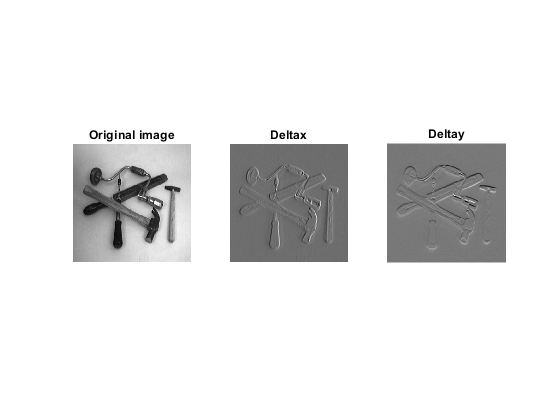

deltax = [1 0 -1; 2 0 -2; 1 0 -1];
deltay = [1 2 1; 0 0 0; -1 -2 -1];
tools = few256;
dxtools = conv2(tools, deltax, 'valid');
dytools = conv2(tools, deltay, 'valid');
figure()
subplot(1,3,1);
showgrey(tools);
title("Original image")
subplot(1,3,2);
showgrey(dxtools);
title("Deltax")
subplot(1,3,3);
showgrey(dytools);
title("Deltay")

We expect to see contrast when the derivative is high in x for the dxtools and similarly for y. This can easily be seen in the screwdriver handle. For y, it has a higher "activation" than in y.

The sizes are different because of the 3x3 filter. conv2 with valid returns only pixels where the whole filter fits, which for a 3x3 filter causes 2 rows and columns to be removed. If we use 'same' instead of 'valid' this doesn't happen. 

**Question 2 & 3.  **Is it easy to ﬁnd a threshold that results in thin edges? Explain why or why not!

Does smoothing the image help to ﬁnd edges?

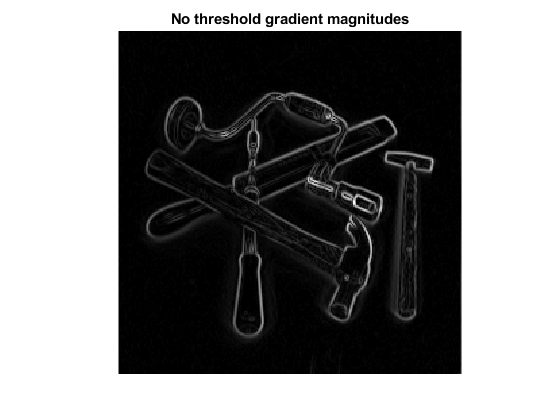

figure()
thresholds = linspace(20,60,16);
gradmagntools = sqrt(dxtools .^2 + dytools .^2);
showgrey(gradmagntools);
title("No threshold gradient magnitudes");

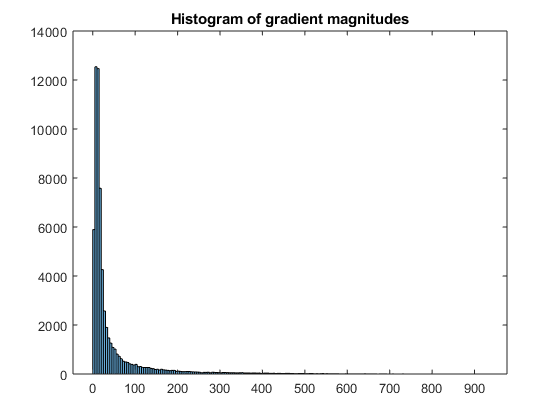

histogram(gradmagntools);
title("Histogram of gradient magnitudes");

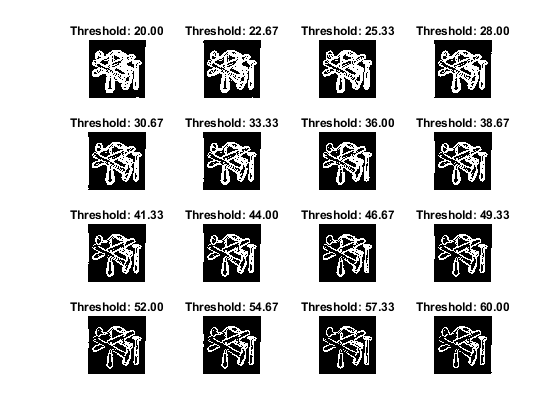


thresholdcomp(tools, thresholds);

It is not easy to find a threshold that results in a smooth image. This could be because of smoothing, which results in wider edges. Smoothing helps with finding edges because it removes a lot of noise reduces the magnitude of the gradient.

**Question 4-6: **What can you observe? Provide explanation based on the generated images.

figure()
house = godthem128;
size(house)

ans =    128   128


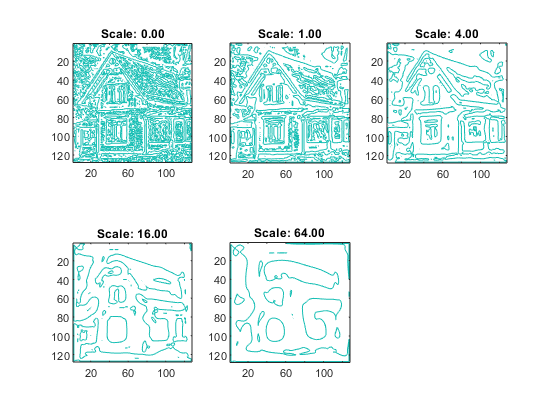

scales = [0.0001, 1.0, 4.0, 16.0, 64.0];
for sc = 1:length(scales)
    subplot(2,3,sc)
    contour(Lvvtilde(discgaussfft(house, scales(sc))), [0 0]);
    axis('image')
    axis('ij')
    title(sprintf("Scale: %0.2f",scales(sc)));
end

When smoothing we blur out edges that correspond to noise. The gradient magnitude reaches a maximum quite often on noisy images.

What is the eﬀect of the sign condition in this diﬀerential expression?

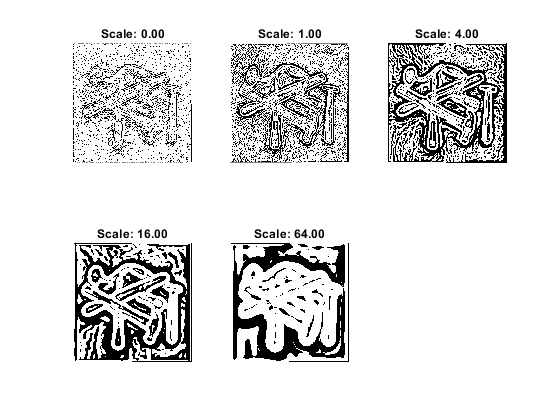

figure()
tools = few256;
for sc = 1:length(scales)
    subplot(2,3,sc)
    showgrey(Lvvvtilde(discgaussfft(tools, scales(sc)))<0);
    axis('image')
    axis('ij')
    title(sprintf("Scale: %0.2f",scales(sc)));
end

The sign condition masks the image into only black and white pixels. White pixels are where the sign is negative, which is where the gradient magnitude can be maximum and edges can be found.

We can conclude that smoothing the image results in removal of finer structures in the image and those edges. The edges, in the house image that remains after smoothing are the house edges.

We can combine the result of Lvv and Lvvv, by considering edges as where Lvv is 0 and Lvvv is negative.

**Question 7**

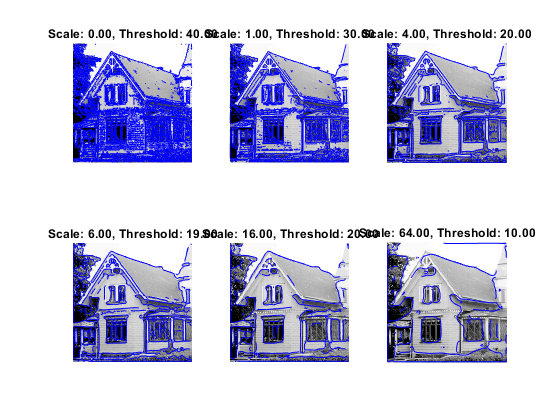

warning('off','all')
figure()
scales = [0.0001, 1.0, 4.0, 6.0,16.0, 64.0];
thresholds = [40, 30, 20, 19, 20, 10];
house = godthem256;
for sc = 1:length(scales)
    subplot(2,3,sc)
    curves = extractedge(house,scales(sc),thresholds(sc));
    overlaycurves(house,curves);
    title(sprintf("Scale: %0.2f, Threshold: %0.2f",scales(sc), thresholds(sc)));
end

**House:**

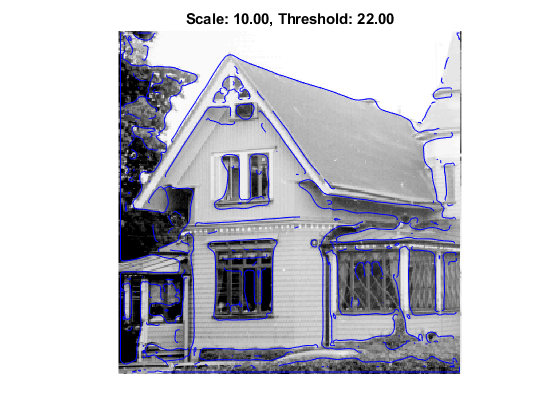

warning('off','all')
house=godthem256;
figure()
scale = 10;
threshold = 22;
curves = extractedge(house,scale,threshold);
overlaycurves(house,curves);
title(sprintf("Scale: %0.2f, Threshold: %0.2f",scale, threshold));

**Tools:**

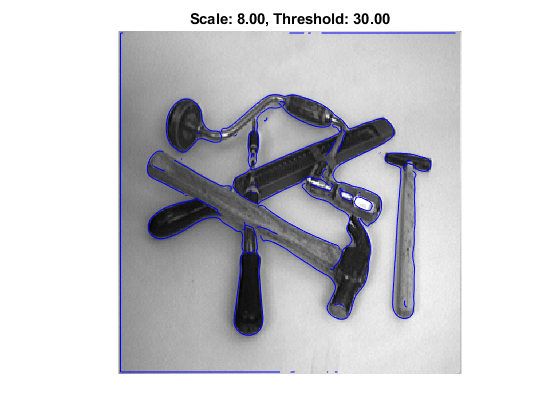

warning('off','all')
figure()
tools = few256;
scale = 8;
threshold = 30;
curves = extractedge(tools,scale,threshold);
overlaycurves(tools,curves);
title(sprintf("Scale: %0.2f, Threshold: %0.2f",scale, threshold));